# Lab 5 by Cole Bardin Section 62

## Aplications of the Inverse Matrix

## Question 1

clc, clear, close all

syms x y;
A = @(x,y) [x, y, 15-x-y; 20-2*x-y, 5, 2*x+y-10; x+y-5, 10-y, 10-x];

% Iterate y1 through each odd number 1-9 except 5
for y1 = [1,3,7,9]
    % Iterate x1 through each even number 2-4
    for x1 = 2:2:8
        % Create magic matrix with x1 y1
        M = A(x1,y1);
        % Assume it is a proper magic
        is_magic = 1;
        % Initialize empty cache for each 9 slots
        cache = zeros(1,9);
        % Iterate through each element
        for i = 1:1:9
            % Set is_magic false if any element<1 or >9
            if M(i) < 1 || M(i) > 9
                is_magic = 0;
            else
                % If number is already found in cache, set false
                if cache(M(i)) == 1
                    is_magic = 0;
                % If not, mark number as found in cache
                else
                    cache(M(i)) = 1;
                end
            end
        end
        % If this matrix did not fail any tests display
        if is_magic == 1
            disp("x="+x1+" y="+y1+" makes a magic matrix:")
            disp(M)
        end
    end
end

x=6 y=1 makes a magic matrix:


     6     1     8
     7     5     3
     2     9     4



x=8 y=1 makes a magic matrix:


     8     1     6
     3     5     7
     4     9     2



x=4 y=3 makes a magic matrix:


     4     3     8
     9     5     1
     2     7     6



x=8 y=3 makes a magic matrix:


     8     3     4
     1     5     9
     6     7     2



x=2 y=7 makes a magic matrix:


     2     7     6
     9     5     1
     4     3     8



x=6 y=7 makes a magic matrix:


     6     7     2
     1     5     9
     8     3     4



x=2 y=9 makes a magic matrix:


     2     9     4
     7     5     3
     6     1     8



x=4 y=9 makes a magic matrix:


     4     9     2
     3     5     7
     8     1     6



## Question 2

clc, clear, close all

syms x y;
A = @(x,y) [x, y, 15-x-y; 20-2*x-y, 5, 2*x+y-10; x+y-5, 10-y, 10-x];

M3 = A(8,1);
r = ones(3,1);
S = r'*M3*r;
disp("Sum of all elements in M3=")

Sum of all elements in M3=


disp(S)

    45



## Question 3

clc, clear, close all

A = sym(pascal(4));
disp("Pascal(4)")

Pascal(4)


disp("Det=")

Det=


disp(det(A))

$$1$$

disp("Adj=")

Adj=


disp(adjoint(A))

$$\left(\begin{array}{cccc} 4 & -6 & 4 & -1\\ -6 & 14 & -11 & 3\\ 4 & -11 & 10 & -3\\ -1 & 3 & -3 & 1 \end{array}\right)$$

disp("Inv=")

Inv=


disp(inv(A))

$$\left(\begin{array}{cccc} 4 & -6 & 4 & -1\\ -6 & 14 & -11 & 3\\ 4 & -11 & 10 & -3\\ -1 & 3 & -3 & 1 \end{array}\right)$$


A = sym(mod(pascal(4),2));
disp("Pascal(4) mod2")

Pascal(4) mod2


disp("Det=")

Det=


disp(det(A))

$$1$$

disp("Adj=")

Adj=


disp(adjoint(A))

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 1\\ 0 & 0 & 1 & -1\\ 0 & 1 & 0 & -1\\ 1 & -1 & -1 & 1 \end{array}\right)$$

disp("Inv=")

Inv=


disp(inv(A))

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 1\\ 0 & 0 & 1 & -1\\ 0 & 1 & 0 & -1\\ 1 & -1 & -1 & 1 \end{array}\right)$$


A = sym(vander(1:4));
disp("vander(1:4)")

vander(1:4)


disp("Det=")

Det=


disp(det(A))

$$12$$

disp("Adj=")

Adj=


disp(adjoint(A))

$$\left(\begin{array}{cccc} -2 & 6 & -6 & 2\\ 18 & -48 & 42 & -12\\ -52 & 114 & -84 & 22\\ 48 & -72 & 48 & -12 \end{array}\right)$$

disp("Inv=")

Inv=


disp(inv(A))

$$\left(\begin{array}{cccc} -\frac{1}{6} & \frac{1}{2} & -\frac{1}{2} & \frac{1}{6}\\ \frac{3}{2} & -4 & \frac{7}{2} & -1\\ -\frac{13}{3} & \frac{19}{2} & -7 & \frac{11}{6}\\ 4 & -6 & 4 & -1 \end{array}\right)$$


A = [1, 2, 3; 4, 5, 6; 7, 8, 9];
disp("1-9")

1-9


disp("Det=")

Det=


disp(det(A))

  -9.5162e-16



disp("Adj=")

Adj=


disp(adjoint(A))

   -3.0000    6.0000   -3.0000
    6.0000  -12.0000    6.0000
   -3.0000    6.0000   -3.0000



disp("Inv=")

Inv=


disp(inv(A))

   1.0e+16 *

    0.3153   -0.6305    0.3153
   -0.6305    1.2610   -0.6305
    0.3153   -0.6305    0.3153



## Question 4

clc, clear, close all
A = eye(1000);
whos A

  Name         Size                Bytes  Class     Attributes

  A         1000x1000            8000000  double              



S = sparse(A);
whos S

  Name         Size              Bytes  Class     Attributes

  S         1000x1000            24008  double    sparse    



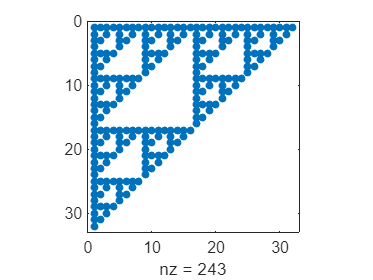


S = sparse(4,3);
A = full(S);

I10 = sparse(eye(10));

i = [1:10, 1:10];
j = [1:10, 10:-1:1];
k = ones(size(i));
A = sparse(i, j, k);

A = sparse([5, 6], [5, 6], [3, -3],10,10); % two nonzero elements in a 10x10 sparse matrix.

clear
p = pascal(32); % Pascal matrix of dimension 16
s = rem(p,2); % remainder of p mod 2 applied to each component
spy(s) % displays 16x16 Sierpinski gasket

## Question 5

clc, clear, close all

A = mod(pascal(4),2); 
A = sym(A);
I = eye(4);
AI = [A, I];
AIR = rref(AI);
disp(AIR(:,5:end))

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 1\\ 0 & 0 & 1 & -1\\ 0 & 1 & 0 & -1\\ 1 & -1 & -1 & 1 \end{array}\right)$$

## Question 6

clc, clear, close all

n = 5;
X = -ones(n-1,1);
Y = 2*ones(n,1);
Z = X;

A  = gallery('tridiag',X,Y,Z);
A = sym(full(A));

disp("Det of tridiag A=")

Det of tridiag A=


disp(det(A))

$$6$$

disp("Inverse of tridiag A=")

Inverse of tridiag A=


disp(inv(A))

$$\left(\begin{array}{ccccc} \frac{5}{6} & \frac{2}{3} & \frac{1}{2} & \frac{1}{3} & \frac{1}{6}\\ \frac{2}{3} & \frac{4}{3} & 1 & \frac{2}{3} & \frac{1}{3}\\ \frac{1}{2} & 1 & \frac{3}{2} & 1 & \frac{1}{2}\\ \frac{1}{3} & \frac{2}{3} & 1 & \frac{4}{3} & \frac{2}{3}\\ \frac{1}{6} & \frac{1}{3} & \frac{1}{2} & \frac{2}{3} & \frac{5}{6} \end{array}\right)$$

disp("Adjoint of tridiag A=")

Adjoint of tridiag A=


disp(adjoint(A))

$$\left(\begin{array}{ccccc} 5 & 4 & 3 & 2 & 1\\ 4 & 8 & 6 & 4 & 2\\ 3 & 6 & 9 & 6 & 3\\ 2 & 4 & 6 & 8 & 4\\ 1 & 2 & 3 & 4 & 5 \end{array}\right)$$

## Question 7

clc, clear, close all

n = 5;
X = -ones(n-1,1);
Y = 2*ones(n,1);
Z = X;

A  = gallery('tridiag',X,Y,Z);
b = [0; 0; 0; 0; 6];

AI = [A, eye(5)];
AIR = rref(AI);
Ainv = AIR(:,n+1:end);
disp("Inverse of tridiag=")

Inverse of tridiag=


disp(Ainv)

    0.8333    0.6667    0.5000    0.3333    0.1667
    0.6667    1.3333    1.0000    0.6667    0.3333
    0.5000    1.0000    1.5000    1.0000    0.5000
    0.3333    0.6667    1.0000    1.3333    0.6667
    0.1667    0.3333    0.5000    0.6667    0.8333




x = Ainv*b;
x = x(:,end);
disp("Solution set=")

Solution set=


disp(x)

     1
     2
     3
     4
     5




disp("Ax-b =")

Ax-b =


disp(A*x - b)

     0
     0
     0
     0
     0



## Question 8

clc, clear, close all

A11 = pascal(3);
A12 = pascal(3);
A12 = A12(:, 1:2);
A21 = zeros(2,3);
A22 = pascal(2);
A = [A11 A12; A21 A22];

B11 = inv(A11)

B11 =     3.0000   -3.0000    1.0000
   -3.0000    5.0000   -2.0000
    1.0000   -2.0000    1.0000


B22 = inv(A22)

B22 =      2    -1
    -1     1


B12 = -1*B11*A12*B22

B12 =    -2.0000    1.0000
    1.0000   -1.0000
         0         0


B = inv(A)

B =      3    -3     1    -2     1
    -3     5    -2     1    -1
     1    -2     1     0     0
     0     0     0     2    -1
     0     0     0    -1     1


## Questions 9-10

clc, clear, close all

message1 = "Beware the Jabberwock, my son!\nThe jaws that bite, the claws that catch!\n";
message2 = "Beware the Jubjub bird,\nand shun The frumious Bandersnatch!\n";
message = message1 + message2; % combine the two strings
message = char(message); % convert to character array
%fprintf(message) % display the full message

A = [1, -2, 2; 2, -1, 2; 2, -2, 3];

% We better encode it, so the Jabberwock is not warned in advance!
while mod(length(message),3) ~= 0
    message = [message ' ']; % Add another space.
end
M = reshape( message, 3, []); % Reshape message into a 3xn matrix
A = [1 -2 2; 2 -1 2; 2 -2 3]; % Matrix to encrypt the message.
coded_message = A*M;

% The son will now decode his father's message using the matrix inverse.
decoder = round( inv(A) );
message_in_a_matrix = decoder*coded_message;
original_message = char( reshape( message_in_a_matrix, 1, [] ) );
fprintf(original_message)

Beware the Jabberwock, my son!
The jaws that bite, the claws that catch!
Beware the Jubjub bird,
and shun The frumious Bandersnatch!
 



coded_message1 = [68 258 278 -34 88 -59 95 121 111 -49 -61 257 109 77 -20 110 240 -53 249 115 121 18 71 86 8 -71 129 -65 133 5 4 -51 110 6 -55 107 144 -23 -61 119 85 30 267 138 38 119 252 115 71 121 140 187 69 105 116 99 -64; 237 402 420 171 309 148 322 342 315 183 159 386 324 289 199 321 372 172 378 329 317 167 294 315 156 142 335 151 349 221 206 182 330 152 150 334 363 193 159 324 303 173 400 355 168 351 384 329 216 198 351 326 284 320 192 326 138; 237 475 504 102 301 70 311 347 321 100 76 466 328 279 130 321 442 90 454 331 328 160 277 301 144 58 345 68 358 166 162 98 327 139 74 329 376 124 76 335 297 172 483 366 171 350 460 331 202 236 364 366 268 322 228 317 60];

message_in_a_matrix = decoder*coded_message1;
original_message = char( reshape( message_in_a_matrix, 1, [] ) );
fprintf(original_message)

Deep in the human unconscious is a pervasive need for a logical universe that makes sense.
But the real universe is always one step beyond logic. - Frank Herbert, Dune
 